**Load golf ball data**

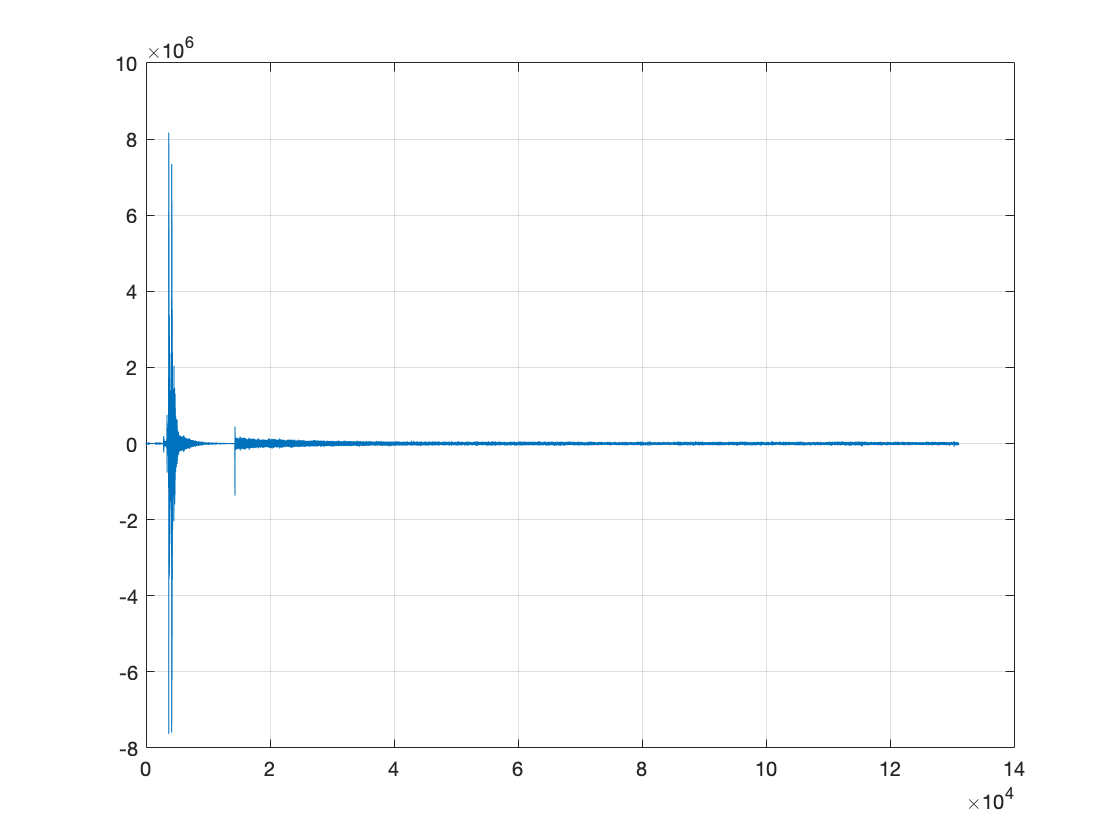

close all;
clear;

% Load golf shot data
filename = 'driver_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 4096; %FFT length
L = 1024; %Window length
overlap = floor(0.65*L); % 50% overlap
N = 0; % User-defined. Used for adaptive threshold later.
W = hanning(L);

**Signal data:**

% SIGNAL
signal = GolfBallData;

**Calling Spectrogram function:**

%Spectrogram 
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,W,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames


**Adaptive threshold using modal intensity + N*(std. dev.):**

hist_length = floor(f_bins/8); % Length hist = 1/8 of num. frames
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:f_bins
       if frame(j) < threshold %If element in frame is less than threshold then set to 0 
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Peak tracking**

freq_at_peaks = zeros(1,nframes);
time_at_peaks = Spec_t;
amplitude = zeros(1,nframes);


for i = 1:nframes
    frame = Spec_mag(:,i); %Current time frame
    
    if max(frame) > 0
        
        %For curve fitting / peak tracking:
        index = find(frame == max(frame)); % Index used to find freq. at peak
        freq_at_peaks(i) = freq(index); % frequency at peak
        

        for j = (index-7):(index+7)
            amplitude(i) = amplitude(i) + 10^(frame(j)/20);
        end

    else
        time_at_peaks(i) = 0;
        
    end
end

frame_width = (length(signal)/nframes); 
end_of_ball_path = floor(((6.5*fs)/frame_width));
frame_at_gain_switch = floor(((0.85*fs)/frame_width));

freq_at_peaks(1:(frame_at_gain_switch+2))=0;
freq_at_peaks(end_of_ball_path:nframes)=0;

time_at_peaks(1:(frame_at_gain_switch+2))=0;
time_at_peaks(end_of_ball_path:nframes)=0;

amplitude(1:(frame_at_gain_switch+2))=0;
amplitude(end_of_ball_path:nframes)=0;

freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);
amplitude = amplitude(amplitude ~= 0);


**Plotting Spectrogram:**

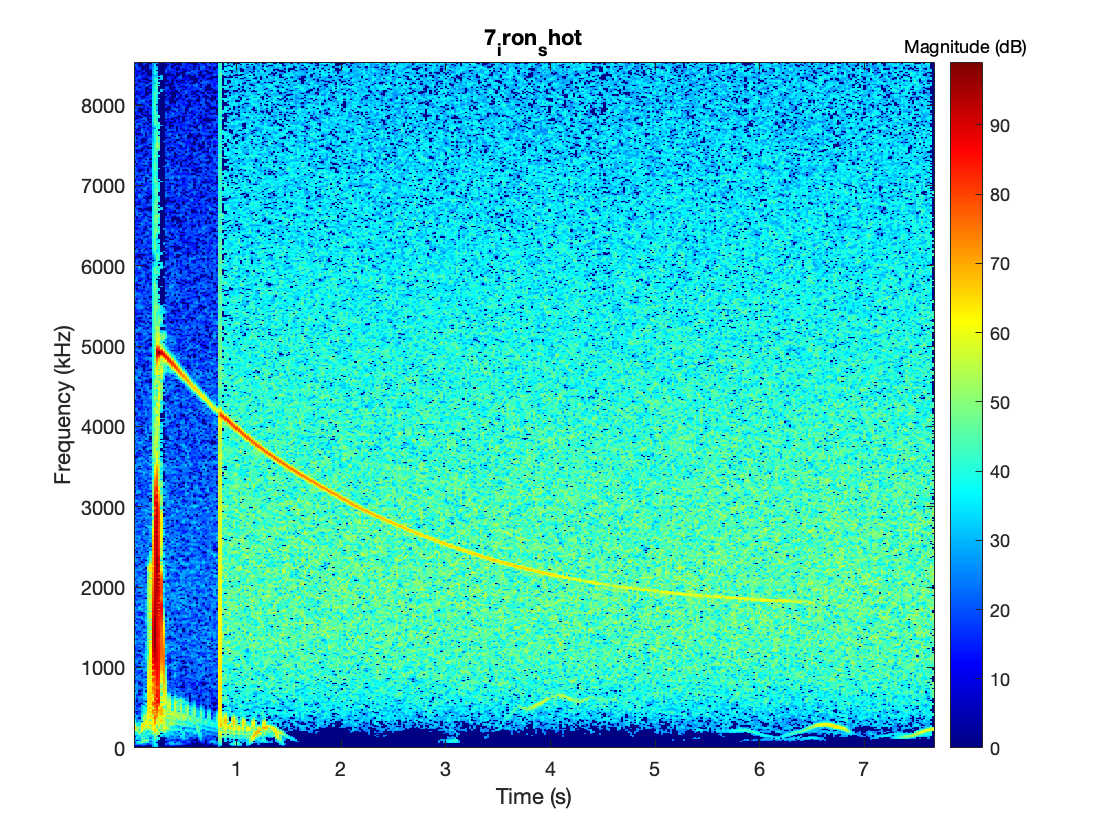

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("7_iron_shot"), xlabel("Time (s)"),ylabel("Frequency (kHz)")

**Curve fitting:**

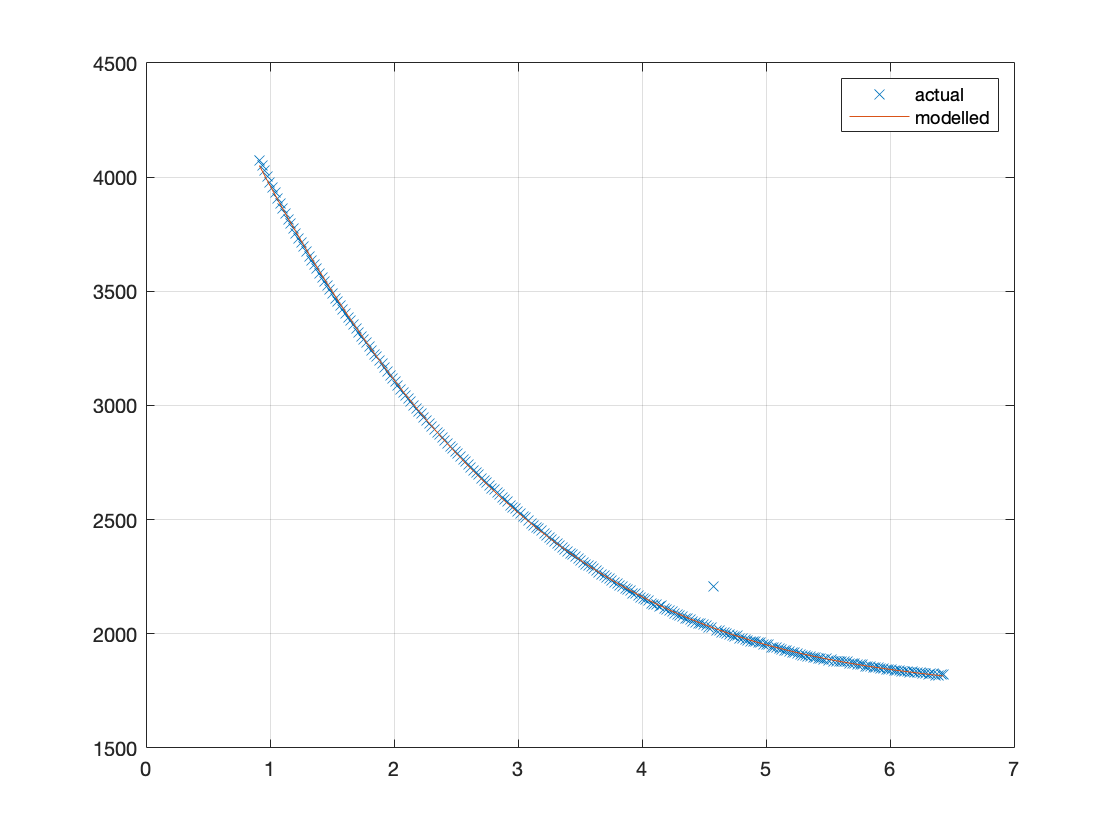

p1 = polyfit(time_at_peaks,freq_at_peaks,3);
f = polyval(p1,time_at_peaks);
plot(time_at_peaks,freq_at_peaks,'x',time_at_peaks,f,'-')
legend('actual','modelled'); grid on;

**Remove outliers:**

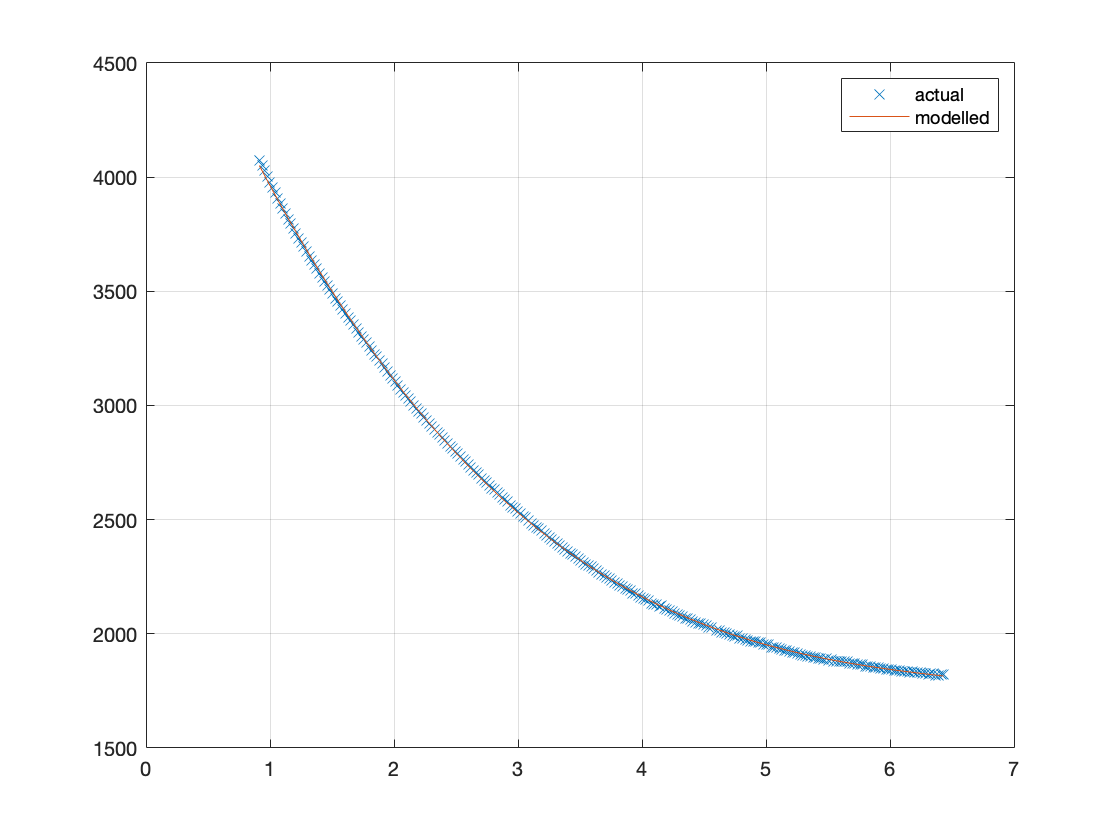

x = time_at_peaks; % Time
y = p1(1)*(x.^3) + p1(2)*(x.^2) + p1(3)*x + p1(4); %Curve fitted function

for i = 1:length(freq_at_peaks)
    if abs(f(i)-freq_at_peaks(i)) > 100
        freq_at_peaks(i) = 0;
        time_at_peaks(i) = 0;
        f(i) = 0;
        amplitude(i) = 0;
    end
end

freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);
amplitude = amplitude(amplitude ~= 0);
f = f(f~=0);

plot(time_at_peaks,freq_at_peaks,'x',time_at_peaks,f,'-')
legend('actual','modelled'); grid on;

**Amplitude plot:**

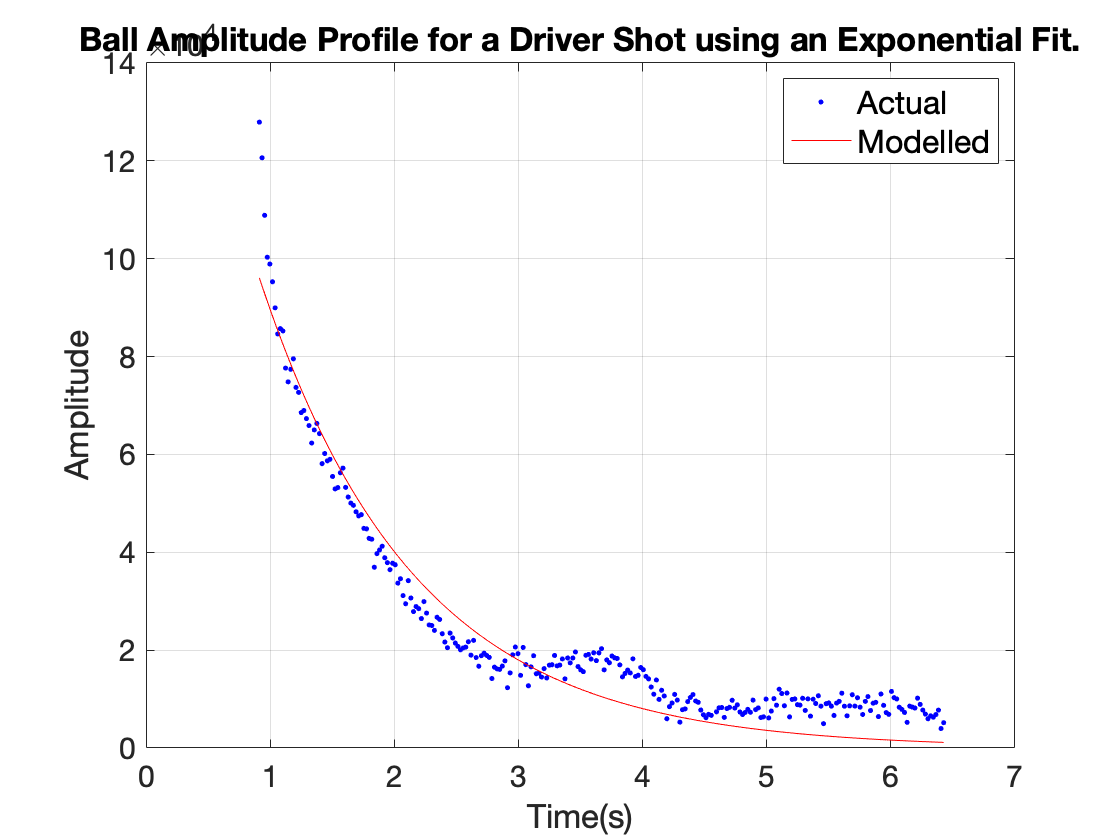


[fit_amp_ball_driver_barsch, Gof_amp_ball_driver_barsch] = ball_driver_amp_fit_exponential(time_at_peaks, amplitude);
set(gca,'FontSize',15);

time_at_peaks_amp_ball_driver_barsch = time_at_peaks;
amplitude_amp_ball_driver_barsch = amplitude;

disp(fit_amp_ball_driver_barsch)

     General model Exp1:
     fit_amp_ball_driver_barsch(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   2.002e+05  (1.883e+05, 2.121e+05)
       b =     -0.8024  (-0.8385, -0.7663)


disp(Gof_amp_ball_driver_barsch)

           sse: 9.3009e+09
       rsquare: 0.9331
           dfe: 260
    adjrsquare: 0.9329
          rmse: 5.9810e+03



%Driver ball amp exponential model
model_at_peaks = feval(fit_amp_ball_driver_barsch,time_at_peaks);
model_at_peaks = model_at_peaks.';
err = abs(model_at_peaks-amplitude);
mean_err = mean(err) 

mean_err = 5.0263e+03

% save('time_at_peaks_amp_ball_driver_barsch.mat','time_at_peaks_amp_ball_driver_barsch')
% save('amplitude_amp_ball_driver_barsch.mat','amplitude_amp_ball_driver_barsch')
% save('fit_amp_ball_driver_barsch.mat','fit_amp_ball_driver_barsch')
% save('Gof_amp_ball_driver_barsch.mat','Gof_amp_ball_driver_barsch')




